T_stop = 0.5000

C_r = 0.0015

V_s_data =     1.0546    1.4798    1.9134    2.3264    2.7441    3.1787    3.6011
    1.0405    1.4582    1.8619    2.2552    2.6524    3.0363    3.4438
    0.9637    1.3524    1.7223    2.0923    2.4641    2.8472    3.2386
    1.0518    1.4629    1.8722    2.2880    2.7123    3.1281    3.5421
    1.0199    1.4180    1.8151    2.2300    2.6271    3.0298    3.4494
    0.9974    1.3927    1.8029    2.1972    2.5924    3.0064    3.4082


R_s = 6.7500

Number of simulations: 50


[14-Jul-2026 20:40:59] Checking for availability of parallel pool...
[14-Jul-2026 20:41:00] Starting Simulink on parallel workers...
[14-Jul-2026 20:41:01] Configuring simulation cache folder on parallel workers...
[14-Jul-2026 20:41:01] Transferring base workspace variables used in the model to parallel workers...
[14-Jul-2026 20:41:01] Loading model on parallel workers...
[14-Jul-2026 20:41:06] Running simulations...
[14-Jul-2026 20:42:01] Completed 1 of 50 simulation runs
[14-Jul-2026 20:42:03] Completed 2 of 50 simulation runs
[14-Jul-2026 20:42:03] Completed 3 of 50 simulation runs
[14-Jul-2026 20:42:03] Completed 4 of 50 simulation runs
[14-Jul-2026 20:42:52] Completed 5 of 50 simulation runs
[14-Jul-2026 20:42:52] Completed 6 of 50 simulation runs
[14-Jul-2026 20:42:53] Completed 7 of 50 simulation runs
[14-Jul-2026 20:42:55] Completed 8 of 50 simulation runs
[14-Jul-2026 20:43:43] Completed 9 of 50 simulation runs
[14-Jul-2026 20:43:45] Completed 10 of 50 simulation runs
[14-Ju

Number of simulations: 50


[14-Jul-2026 20:51:53] Checking for availability of parallel pool...
[14-Jul-2026 20:51:54] Starting Simulink on parallel workers...
[14-Jul-2026 20:51:54] Configuring simulation cache folder on parallel workers...
[14-Jul-2026 20:51:54] Transferring base workspace variables used in the model to parallel workers...
[14-Jul-2026 20:51:55] Loading model on parallel workers...
[14-Jul-2026 20:52:00] Running simulations...
[14-Jul-2026 20:52:57] Completed 1 of 50 simulation runs
[14-Jul-2026 20:52:59] Completed 2 of 50 simulation runs
[14-Jul-2026 20:52:59] Completed 3 of 50 simulation runs
[14-Jul-2026 20:52:59] Completed 4 of 50 simulation runs
[14-Jul-2026 20:53:50] Completed 5 of 50 simulation runs
[14-Jul-2026 20:53:50] Completed 6 of 50 simulation runs
[14-Jul-2026 20:53:53] Completed 7 of 50 simulation runs
[14-Jul-2026 20:53:53] Completed 8 of 50 simulation runs
[14-Jul-2026 20:54:40] Completed 9 of 50 simulation runs
[14-Jul-2026 20:54:41] Completed 10 of 50 simulation runs
[14-Ju

Number of simulations: 50


[14-Jul-2026 21:03:01] Checking for availability of parallel pool...
[14-Jul-2026 21:03:01] Starting Simulink on parallel workers...
[14-Jul-2026 21:03:01] Configuring simulation cache folder on parallel workers...
[14-Jul-2026 21:03:01] Transferring base workspace variables used in the model to parallel workers...
[14-Jul-2026 21:03:03] Loading model on parallel workers...
[14-Jul-2026 21:03:15] Running simulations...
[14-Jul-2026 21:04:16] Completed 1 of 50 simulation runs
[14-Jul-2026 21:04:17] Completed 2 of 50 simulation runs
[14-Jul-2026 21:04:18] Completed 3 of 50 simulation runs
[14-Jul-2026 21:04:18] Completed 4 of 50 simulation runs
[14-Jul-2026 21:05:08] Completed 5 of 50 simulation runs
[14-Jul-2026 21:05:09] Completed 6 of 50 simulation runs
[14-Jul-2026 21:05:10] Completed 7 of 50 simulation runs
[14-Jul-2026 21:05:11] Completed 8 of 50 simulation runs
[14-Jul-2026 21:06:00] Completed 9 of 50 simulation runs
[14-Jul-2026 21:06:00] Completed 10 of 50 simulation runs
[14-Ju

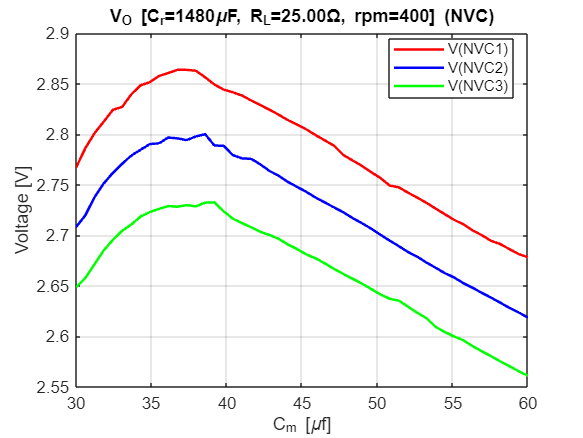

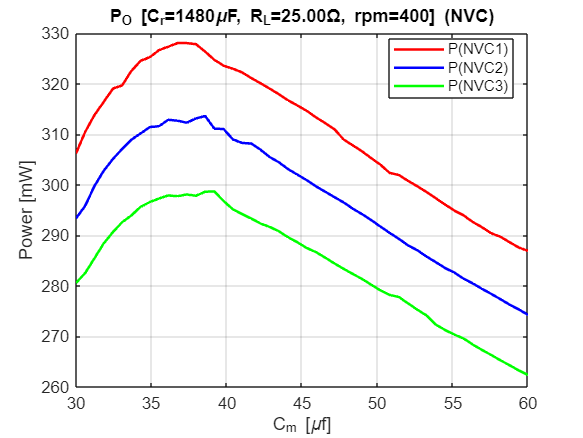

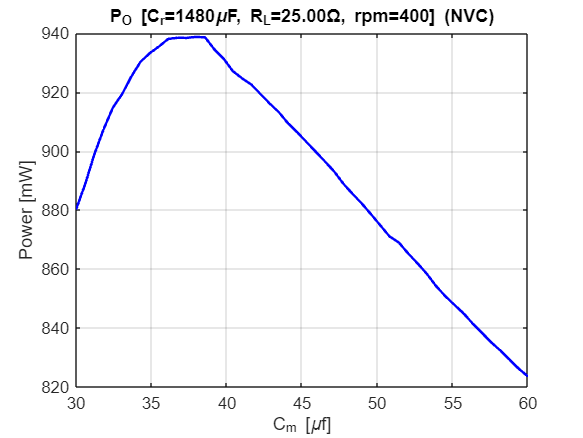

Elapsed time is 2251.754059 seconds.



% Dati misurati (D1_f_sweep.csv, D2_f_sweep.csv):
% sweep di rpm per 7 valori fissi del condensatore di compensazione C_m,
% sommati sui due bridge FWR-Delta per ottenere la potenza totale e il rendimento.
% R_L = 7 Ohm fisso (stesso valore riportato in entrambi i CSV).
% NOTA: i CSV originali usano il punto "." come separatore delle migliaia (es. "1.147,796"
% mW); nell'export e' stato sostituito da una virgola, dando un formato a tre gruppi
% "1,147,796" che va decodificato come 1147.796 mW (i gruppi prima dell'ultimo
% costituiscono la parte intera, l'ultimo gruppo sono i millesimi).

% CORREZIONI (valori anomali di un ordine di grandezza rispetto alle celle vicine della
% stessa riga, stesso tipo di errore di virgola gia' visto nel C_sweep/R_sweep):
%   D1, rpm=200, C_m=530uF : Po  49.817  -> 498.17
%   D1, rpm=250, C_m=200uF : Pi 177.323  -> 1773.23
%   D2, rpm=400, C_m=630uF : Po 181.742  -> 1817.42
%
% Per C_m = 630 uF e C_m = 47 uF e' disponibile anche la misura reale con i due bridge
% gia' collegati in parallelo (D_1+2_f_sweep.csv, R_L = 5 Ohm, nessun dato di Pi): queste
% due colonne nel grafico di P_O usano la misura reale al posto della somma calcolata dei
% bridge singoli; le altre 5 colonne (530/430/330/200/100 uF) restano la somma calcolata
% a R_L = 7 Ohm. Il grafico di efficienza resta invariato (calcolato dai bridge singoli),
% perche' il file della misura in parallelo non contiene Pi.

C_r = 1480e-6;      % F - condensatore di filtro/raddrizzatore, fisso
R_L = 7;            % Ohm - carico fisso dei bridge singoli (le due curve "misura reale" sotto sono a R_L=5 Ohm)

rpm_plot = [100 150 200 250 300 350 400];
C_L_plot = [630 530 430 330 200 100 47]*1e-6;   % F
n_CL = numel(C_L_plot);
colors = lines(n_CL);

% Potenza totale = somma dei due bridge singoli, colonne = C_L_plot, righe = rpm_plot
P_real_tot_mW = [ ...
     180.078  174.988  162.732  152.033  122.758   94.025   44.058; ...
     510.993  504.859  491.896  484.650  403.460  330.115  200.065; ...
     978.613  983.821  983.860  993.712  829.777  731.293  507.253; ...
    1555.031 1570.307 1592.833 1630.697 1283.158 1296.169  982.594; ...
    2193.115 2226.615 2259.897 2316.580 1856.230 1937.356 1636.655; ...
    2875.278 2932.158 2973.314 3065.878 2479.616 2629.869 2525.935; ...
    3572.547 3644.024 3702.378 3808.189 3082.439 3278.090 3524.902];
P_real_tot = P_real_tot_mW/1000;

% Potenza reale misurata con i due bridge gia' in parallelo (D_1+2_f_sweep.csv, R_L=5 Ohm),
% disponibile solo per C_m = 630 uF (colonna 1) e C_m = 47 uF (colonna 7)
Po_meas_630_mW = [148.722 430.397 840.144 1339.088 1906.131 2485.999 3106.791];
Po_meas_47_mW  = [64.545  277.332 676.425 1236.093 1969.002 2691.710 3681.635];

P_real_tot(:,1) = Po_meas_630_mW/1000;   % sostituisce la colonna C_m=630uF con la misura reale
P_real_tot(:,n_CL) = Po_meas_47_mW/1000; % sostituisce la colonna C_m=47uF con la misura reale

% Rendimento di raddrizzamento eta_rec = P_O/P_I, stessa disposizione righe/colonne
% (invariato: calcolato dai bridge singoli, nessun dato Pi per la misura in parallelo)
eta_in = [ ...
    0.2931 0.3039 0.2674 0.2612 0.2625 0.2423 0.1748; ...
    0.3736 0.3904 0.3535 0.3518 0.3546 0.3303 0.2685; ...
    0.4196 0.4343 0.4056 0.4102 0.4114 0.3897 0.3336; ...
    0.4524 0.4639 0.4368 0.4467 0.4373 0.4332 0.3812; ...
    0.4764 0.4827 0.4645 0.4700 0.4644 0.4634 0.4202; ...
    0.4806 0.4970 0.4861 0.4886 0.4870 0.4871 0.4553; ...
    0.5074 0.5087 0.5011 0.5028 0.5042 0.5041 0.4831];

% PEE (Power Extraction Efficiency = P_real/P_matched) omessa per ora:
% manca il riferimento di potenza a carico adattato P_matched(rpm) (vedi f_sweep NVC).


figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, P_real_tot(:,k)*1000, 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('P_O [C_r=%.0f\\muF, R_L=%.2f\\Omega tranne dove indicato]', C_r*1e6, R_L));
xlabel('rpm');
ylabel('Power [mW]');

legendEntries_Po = cell(1, n_CL);
for k = 1:n_CL
    if k == 1 || k == n_CL
        legendEntries_Po{k} = sprintf('C_m = %.0f \\muF (misura reale, R_L=5\\Omega)', C_L_plot(k)*1e6);
    else
        legendEntries_Po{k} = sprintf('C_m = %.0f \\muF (somma calcolata)', C_L_plot(k)*1e6);
    end
end
legend(legendEntries_Po, 'Location', 'best');
hold off;


%{
%%%PEE
figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, Pee(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('PEE = P_{Real} / P_{Matched} [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L));
xlabel('rpm');
ylabel('PEE');

legendEntries = cell(1, n_CL);
for k = 1:n_CL
    legendEntries{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries, 'Location', 'best');
hold off;
%}


%%%efficiency
figure;
hold on;
for k = 1:n_CL
    plot(rpm_plot, eta_in(:,k), 'o-', 'LineWidth', 1.5, 'Color', colors(k,:));
end
grid on;
title(sprintf('\\eta_{rec} = P_{O} / P_{I} [C_r=%.0f\\muF, R_L=%.2f\\Omega]', C_r*1e6, R_L));
xlabel('rpm');
ylabel('\eta_{rec}');

legendEntries_eta = cell(1, n_CL);
for k = 1:n_CL
    legendEntries_eta{k} = sprintf('C_m = %.0f \\muF', C_L_plot(k)*1e6);
end
legend(legendEntries_eta, 'Location', 'best');
hold off;
